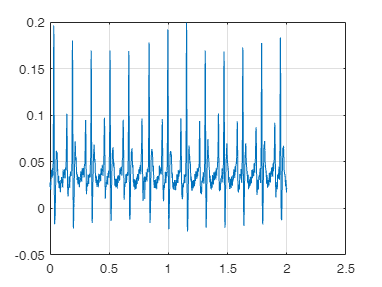

[x, fs] = audioread('D:/raterawwithduplicate/12.wav');
y=x(100*6250:102*6250);
t=linspace(0,length(y)/fs,length(y));
figure()
plot(t,y);
grid("on");

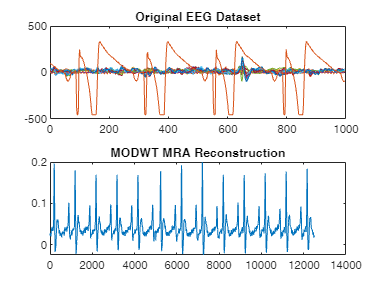

[wt,mra] = dlmodwt(y,DataFormat='TCB');
xrec = sum(mra);
subplot(2,1,1)
plot(Espiga3)
title("Original EEG Dataset")
subplot(2,1,2)
plot(extractdata(squeeze(xrec))')
title("MODWT MRA Reconstruction")